# Complex-symbol-to-bits Demapping for IQ Modulations

This functions demaps a complex symbol stream into a bit stream with respect to some QAM constellations using gray coding.

**Inputs:**

- *symb_RX_estimated*: estimated symbol stream vector of size *nb_symb x 1*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_symb*: number of symbols in the  symbol stream (= length of *symb_RX*)

**Ouputs:**

- *bit_RX*: estimated bit stream vector of size *nb_bit x 1* where *nb_bit = nb_bit_per_symb x nb_symb*

function bit_RX = demapping_QAM( symb_RX_estimated , nb_bit_per_symb , nb_symb )

nb_bit = nb_symb * nb_bit_per_symb ;                  % Number of bits of the bit stream
bit_RX = zeros( nb_bit , 1 ) ;                        % Bit stream vector initialization

## 4QAM constellation (<=> QPSK)

The de-mapping for the QPSK constellation should be done as shown below:

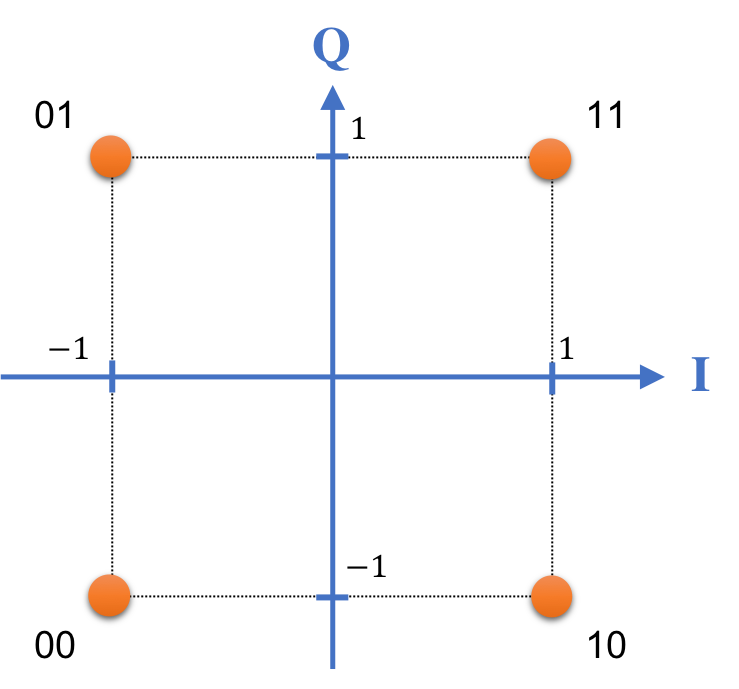

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 2
    QAM_4 = [-1-1i, -1+1i, 1+1i, 1-1i];  % QPSK constellation points
    bit_RX = [];  % Initialize an empty array to hold the decoded bits
    
    for i = 1:nb_symb
        if symb_RX_estimated(i) == QAM_4(1)
            bit = [0; 0];  % Column vector for the bit pair
        elseif symb_RX_estimated(i) == QAM_4(2)
            bit = [0; 1];  % Column vector for the bit pair
        elseif symb_RX_estimated(i) == QAM_4(3)
            bit = [1; 1];  % Column vector for the bit pair
        elseif symb_RX_estimated(i) == QAM_4(4)
            bit = [1; 0];  % Column vector for the bit pair
        end
        % Append each bit as a new row in bit_RX
        bit_RX = [bit_RX; bit];
    end
end





## 16QAM constellation

The de-mapping for the 16QAM constellation should be done as shown below:

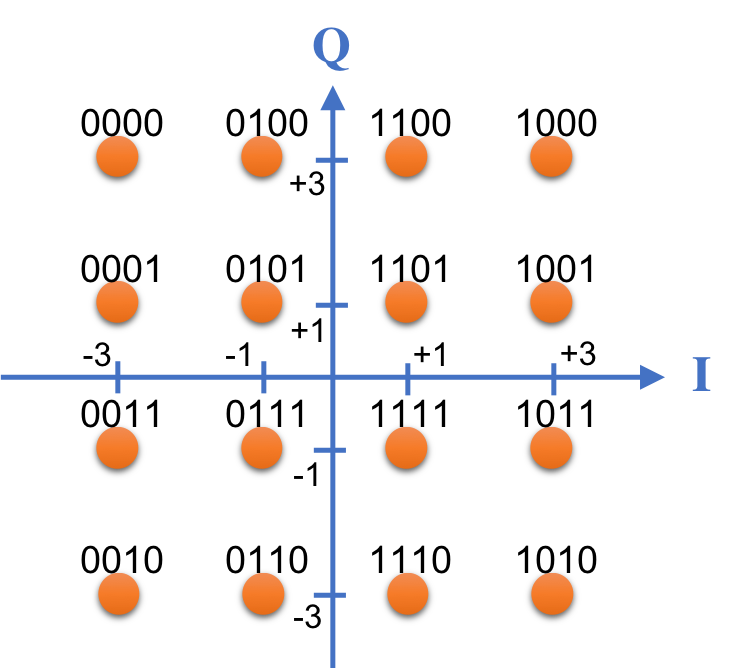

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 4

    %Qam_16 =   0000 ,  0001 ,  0010 ,  0011 ,  0100 ,  0101 ,  0110 ,  0111 , 1000 , 1001 , 1010 , 1011 , 1100 , 1101 , 1110 , 1111  
    QAM_16 = [ -3+3i , -3+1i , -3-3i , -3-1i , -1+3i , -1+1i , -1-3i , -1-1i , 3+3i , 3+1i , 3-3i , 3-1i , 1+3i , 1+1i , 1-3i , 1-1i ];
    
    % Corresponding bit patterns for the 16-QAM constellation points
    bit_patterns = [0 0 0 0;  % 0000
                    0 0 0 1;  % 0001
                    0 0 1 0;  % 0010
                    0 0 1 1;  % 0011
                    0 1 0 0;  % 0100
                    0 1 0 1;  % 0101
                    0 1 1 0;  % 0110
                    0 1 1 1;  % 0111
                    1 0 0 0;  % 1000
                    1 0 0 1;  % 1001
                    1 0 1 0;  % 1010
                    1 0 1 1;  % 1011
                    1 1 0 0;  % 1100
                    1 1 0 1;  % 1101
                    1 1 1 0;  % 1110
                    1 1 1 1]; % 1111

    bit_RX = [];  % Initialize an empty array to hold the decoded bits
    
    % Map each estimated symbol to the corresponding bit pattern
    for i = 1:nb_symb
        % Find the index of the estimated symbol in the QAM_16 constellation
        idx = find(symb_RX_estimated(i) == QAM_16);
        
        % Get the corresponding bit pattern
        bit = bit_patterns(idx, :)';
        
        % Append each bit as a new row in bit_RX
        bit_RX = [bit_RX; bit];
    end
end

end